# Lambda chooser

names = ["drift x", "drift y", "hysteresis x", "hysteresis y", "creep x", "creep y"];

drift      = [0 0; 4 4];    % 0 to 10
hyst       = [0 0; 4 4];    % 0 to 10
creep      = [0 0; 4 4];    % 0 to 10
noise_minl = [9; 11];       % 1 to 15
noise_mag  = [0.9; 1.1];    % 0.1 to 2
weights    = [1 1 0.05];       % distortion, noise, proportion

weights = weights/sum(weights);

dist = [drift hyst creep];

if any(dist(2,:)<dist(1,:))
    errcause = find(dist(2,:)<dist(1,:));
    errcont = "";
    for ctr = 1:length(errcause)
        errcont = errcont + " " + names(errcause(ctr));
    end
    error("ERROR! A maximum distortion (in" + errcont + ") is smaller than a minimum.")
end

dist(3,:) = abs(mean(dist));
condition = dist(2,:)<0;
dist(1:2,condition) = [zeros(1,nnz(condition)), -dist(2,condition)];
condition = dist(1,:).*dist(2,:)<0;
dist(1:2,condition) = [zeros(1,nnz(condition)), max(-dist(1,condition),dist(2,condition))];

if any(dist(2,:)>10)
    errcause = find(dist(2,:)>10);
    dist(2,errcause) = 10;
    errcont = "";
    for ctr = 1:length(errcause)
        errcont = errcont + " " + names(errcause(ctr));
    end
    warning("The absolute value/s of the limit/s of [" ...
        + errcont + "] was/were greater than 10. These are set to 10 instead.");
end

if noise_minl(1)<1
    noise_minl(1) = 1;
    warning("Minimum of the minimum noise undulation width is less than 1. Value is set to 1.");
end
if noise_minl(2)<1
    noise_minl(2) = 15;
    warning("Minimum of the minimum noise undulation width is greater than 15. Value is set to 15.");
end
if noise_mag(1)<0.1
    noise_mag(1) = 0.1;
    warning("Noise magnitude is less than 0.1. Value is set to 0.1.");
end
if noise_mag(2)>2
    noise_mag(2) = 2;
    warning("Noise magnitude is greater than 2. Value is set to 2.");
end

## Load and initiate

% distortion data
ella = [0.057:0.001:0.059 0.06:0.005:0.095 0.1:0.01:0.3];
maglist = 0:0.01:10;

sella = length(ella);
smaglist = length(maglist);

confidence_level = 0.9999999;
zscore = zscorer(confidence_level);

meanErrs = zeros(6,smaglist,sella);
stdErrs = zeros(6,smaglist,sella);
pixprop = zeros(1,sella);

idx = 1;
for ell = ella
    load("lambda_" + ell + ".mat");
    meanErrs(:,:,idx) = S.meanErr;
    stdErrs(:,:,idx) = S.stdErr;
    pixprop(idx) = S.pixprop;
    idx = idx + 1;
end

meanErrs = permute(meanErrs, [3 2 1]);
stdErrs = permute(stdErrs, [3 2 1]);

% noise data
nella = [0.1 0.2 0.3];

nminllist = [1 2 5 10 15];
nmaglist = [0.1:0.1:0.9 1:0.25:2];

load Lambda_vs_noise.mat

nmeanErrs = means;
nstdErrs = stds;

## Interpolate

% % distortion
% queries = 0.057:0.001:0.3;
% 
% meanErrI = zeros(length(queries),smaglist-1,6);
% stdErrI = zeros(length(queries),smaglist-1,6);
% 
% for ctr = 1:6
%     meanErrI(:,:,ctr) = interp1(ella,meanErrs(:,2:end,ctr),queries,"pchip");
%     stdErrI(:,:,ctr) = interp1(ella,stdErrs(:,2:end,ctr),queries,"pchip");
% end
% 
% % noise
% minlq = 1:0.1:15;
% maglq = 0.1:0.01:2;
% 
% [nqueries_min, nqueries_mag] = meshgrid(minlq,maglq);
% 
% [nminllistq, nmaglistq] = meshgrid(nminllist,nmaglist);
% 
% nmeanErrI = zeros(length(maglq),length(minlq),3);
% nstdErrI = zeros(length(maglq),length(minlq),3);
% 
% for ctr = 1:3
%     nmeanErrI(:,:,ctr) = interp2(nminllistq,nmaglistq,nmeanErrs(:,:,ctr), ...
%         nqueries_min,nqueries_mag,"linear");
%     nstdErrI(:,:,ctr) = interp2(nminllistq,nmaglistq,nstdErrs(:,:,ctr), ...
%         nqueries_min,nqueries_mag,"linear");
% end

Uncomment to plot everything.

% [x, y] = meshgrid(queries,maglist);
% 
% x = x(2:end,:);
% y = y(2:end,:);
% 
% for ctr = 1:6
%     figure;
%     means = squeeze(meanErrI(:,:,ctr))';
%     stds = squeeze(stdErrI(:,:,ctr))';
%     surf(x,y,means+stds*zscore,"FaceAlpha",0.8);
%     hold on
% %     surf(x,y,means-zscore*stds,'FaceAlpha',0.2);
%     colormap(jet);
%     xlabel("$\Lambda_u$ [lattice constant$^{-1}$]","Interpreter","latex");
%     ylabel("maximum " + names(ctr) + " magnitude [lattice constant]","Interpreter","latex");
%     zlabel("relative error","Interpreter","latex");
%     shading interp
%     axis tight
%     set(gca,'zscale','log');
%     set(gca, "ColorScale","log");
%     zlim([0.001 1])
%     surf(x,y,means,'edgecolor','none','FaceColor','k','FaceAlpha',0.5);
% %     clim([min(means(:)) max(means(:))]);
%     colorbar;
%     clim([0.001 1])
%     legend('Max error (99%+ confidence)','Mean error','Location','northeast');
%     title(names(ctr));
%     hold off
% %     saveas(gcf,"lambda vs noise " + names(ctr) + ".fig");
% end
% 
% for ctr = 1:3
%     x = nqueries_min;
%     y = nqueries_mag;
%     figure;
%     surf(x,y,zscore*nstdErrI(:,:,ctr)+nmeanErrI(:,:,ctr),'FaceAlpha',0.8);
%     shading interp
%     colormap(jet);
%     xlabel("$\lambda_{min}$ [lattice constant]","Interpreter","latex");
%     ylabel("noise magnitude [lattice constant]","Interpreter","latex");
%     zlabel("absolute error [pixel]","Interpreter","latex");
%     axis tight
%     set(gca,'zscale','log');
%     set(gca, "ColorScale","log");
%     zlim([0.0001 1])
%     hold on
%     surf(x,y,nmeanErrI(:,:,ctr),'edgecolor','none','FaceColor','k','FaceAlpha',0.5);
% %     surf(x,y,-zscore*stds(:,:,ctr)+means(:,:,ctr),'edgecolor','none','FaceColor','k','FaceAlpha',0.25);
%     colorbar;
% %     clim([min(nmeanErrI(:)) max(nmeanErrI(:))]);
%     clim([0.001 1])
%     legend('Max error (96% confidence)','Mean error','Location','northeast');
%     title("$\Lambda_u = " + nella(ctr) + "$","Interpreter","latex");
%     view([60.682 9.302])
%     hold off
% %     saveas(gcf,"lambda " + lambda(ctr) + " vs noise.fig");
% end

## Fast

For performance, let's interpolate after selecting the bounds.

queries = 0.057:0.001:0.3;

% distortion
dsum = zeros(length(queries),6);

for ctr = 1:6
    band = floor(100*dist(1,ctr))+1:ceil(100*dist(2,ctr));
    meanErrIf = interp1(ella,meanErrs(:,band,ctr),queries,"pchip");
    stdErrIf = interp1(ella,stdErrs(:,band,ctr),queries,"pchip");
    dsum(:,ctr) = mean(meanErrIf+stdErrIf*zscore,2);
end

dscore = mean(dsum.*dist(3,:),2)';

% noise
minlq = noise_minl(1):0.1:noise_minl(2);
maglq = noise_mag(1):0.01:noise_mag(2);

[nqueries_min, nqueries_mag] = meshgrid(minlq,maglq);

[nminllistq, nmaglistq] = meshgrid(nminllist,nmaglist);

nmeanErrI = zeros(length(maglq),length(minlq),3);
nstdErrI = zeros(length(maglq),length(minlq),3);

for ctr = 1:3
    nmeanErrI(:,:,ctr) = interp2(nminllistq,nmaglistq,nmeanErrs(:,:,ctr), ...
        nqueries_min,nqueries_mag,"linear");
    nstdErrI(:,:,ctr) = interp2(nminllistq,nmaglistq,nstdErrs(:,:,ctr), ...
        nqueries_min,nqueries_mag,"linear");
end

nscore = interp1([0.1 0.2 0.3],squeeze(mean(nmeanErrI+zscore*nstdErrI,[1 2])), ...
    queries,"pchip");

% proportion
pscore = 1-interp1(ella,pixprop,queries,'spline');

finalscore = weights(1)*dscore+weights(2)*nscore+weights(3)*pscore;

[opt_rel, opt_idx]= min(finalscore);
opt_lambda = queries(opt_idx)

opt_lambda = 0.1850

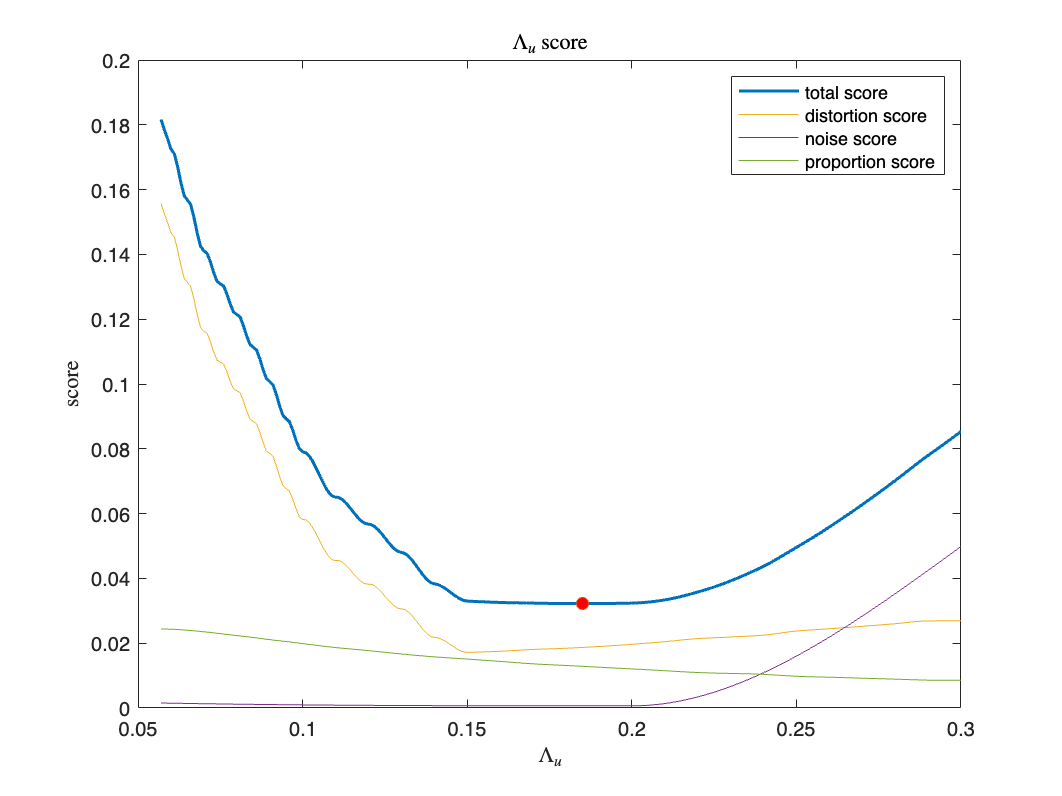


plot(queries,finalscore,'LineWidth',1.5);
hold on
plot(opt_lambda,opt_rel,'LineStyle','none','Marker','o','MarkerFaceColor','red','HandleVisibility','off');
plot(queries,weights(1)*dscore);
plot(queries,weights(2)*nscore);
plot(queries,weights(3)*pscore);
xlabel('$\Lambda_u$','Interpreter','latex');
ylabel('score','Interpreter','latex');
legend('total score','distortion score','noise score','proportion score','Location','northeast');
title("$\Lambda_u$ score",'Interpreter','latex');
hold off